**Ejemplo_XOR_B**

Dos entradas x1 y x2

n1 = x1 or x2 

n2 = x1 nand x2

n3 = n1 and n2

Finalmente tenemos que n3 realiza la operacion XOR  

clear all

x1 = 0

x1 = 0

x2 = 0

x2 = 0

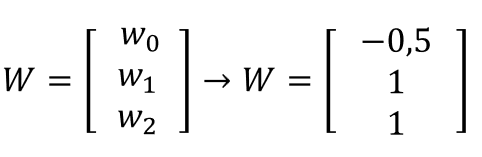

w1 = [-0.5 ; 1 ; 1]     % Pesos de la compuerta OR

w1 =    -0.5000
    1.0000
    1.0000


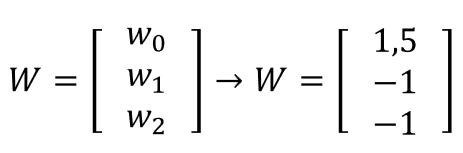

w2 = [1.5 ; -1 ; -1]     % Pesos de la compuerta NAND

w2 =     1.5000
   -1.0000
   -1.0000


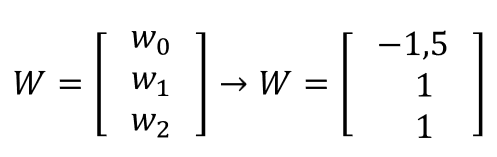

w3 = [-1.5 ; 1 ; 1]     % Pesos de la compuerta AND

w3 =    -1.5000
    1.0000
    1.0000


Definimos el bias, el vector de entrada, fucnion de activacion.

bias = 1

bias = 1

f = 0

f = 0

x = [bias x1 x2]'

x =      1
     0
     0


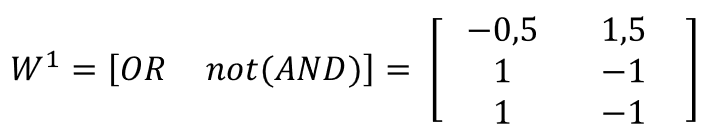

W = [w1  w2]

W =    -0.5000    1.5000
    1.0000   -1.0000
    1.0000   -1.0000


Realizamos la operacion entre el vector de entrada y la capa oculta.

y = operador(W, x) 

y =    -0.5000
    1.5000


y = activacion(y, f) 

y =      0
     0


Creamos el vector de enetrada para la capa de salida.

xo = [bias ; y]

xo =      1
     0
     0


Realizamos la operacion entre el vector de salida de la capa oculta y la capa salida.

y = operador(w3, xo) 

y = -1.5000

y = activacion(y, f) 

y = 0

Funcion de activacion 

function [salida] = activacion(y, umbral) 

[fil, col] = size(y);

    for i=1 : fil
        if y > umbral
            salida(i,1) = 1;
        else 
            salida(i,1) = 0;
        end    
    end    
end

Funcion de operacion 

function [suma] = operador(W, x) 

    [fil, col] = size(W);
    
    for i = 1 : col
    
        suma(i,1) = 0;
    
        for j = 1 : fil  
            suma(i,1) = suma(i,1) + (W(j,i)* x(j,1));  
        end    
    end

end